# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 김동영**

**학번**** : 201710877**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/DongYeongKim123/DSP.git**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

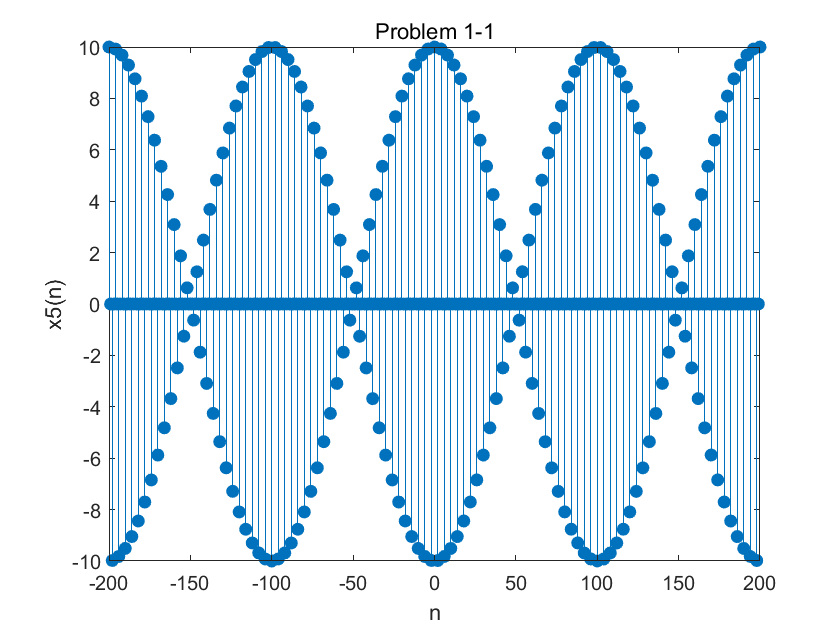

n = -200:1:200;                            % n범위 정의
x = 5*[cos(0.49*pi*n)+cos(0.51*pi*n)];     % x 값 정의 

stem(n,x,'filled');
title('Problem 1-1');
xlabel('n'); ylabel('x5(n)');

2) 

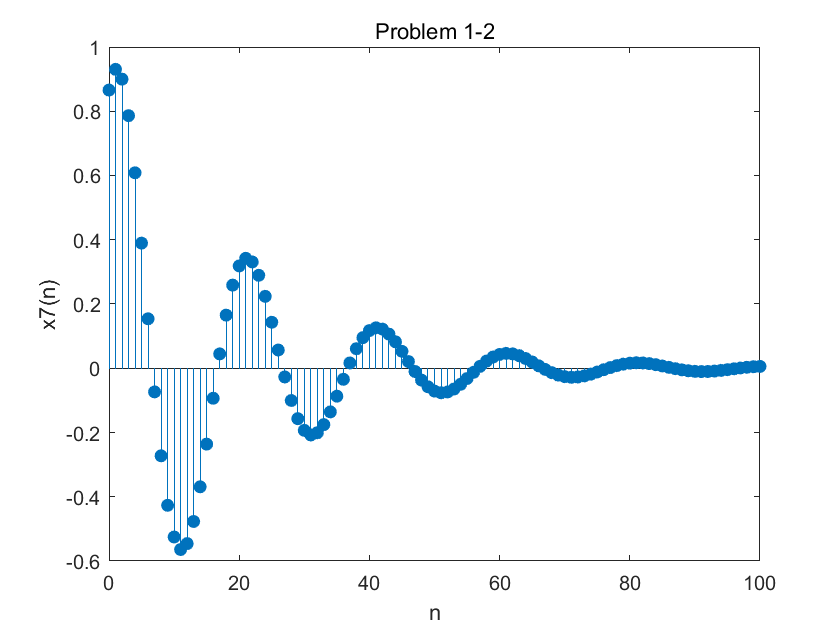

n = 0:1:100;                              % n 범위 정의
x = exp(-0.05*n).*sin(0.1*pi*n+pi/3);     % x 값 정의

stem(n,x,'filled');
title('Problem 1-2');
xlabel('n'); ylabel('x7(n)');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

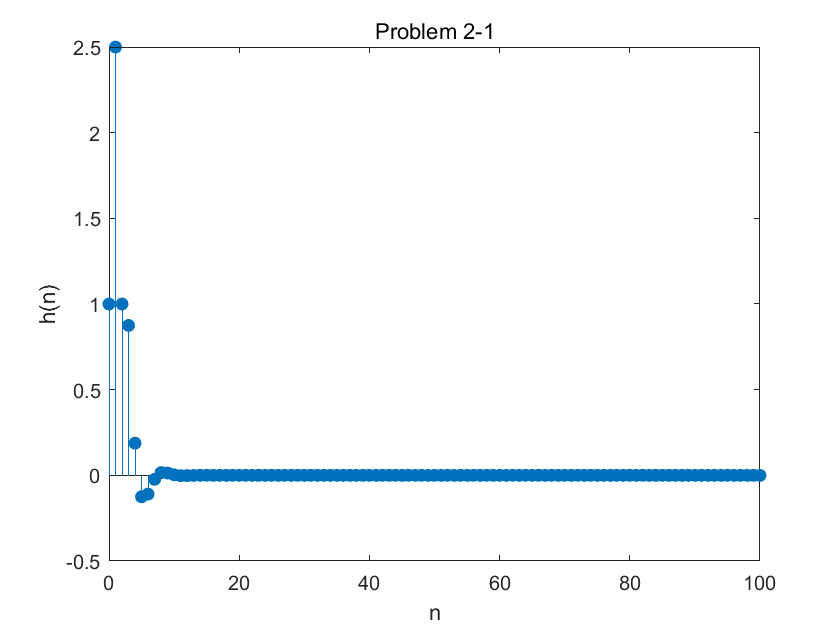

b = [1,2,0,1];                            % bm 정의
a = [1,-0.5,0.25];                        % ak 정의
n = 0:1:100;                              % n 범위 정의
h = impz(b,a,n);                          % 차분방정식으로 포현된 식의 h(n) 구하기

stem(n,h,'filled');
title('Problem 2-1');
xlabel('n'); ylabel('h(n)');

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))                               

ans = 5.8571

% h(n)의 그래프에서 n>100 인 범위에서 거의 0이므로 모든 n에 대한 |h(n)|의 합을 sum(abs(h)) 으로 표현 가능하다.
% 값이 수렴하므로 이 시스템은 안정함을 보여준다.

3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

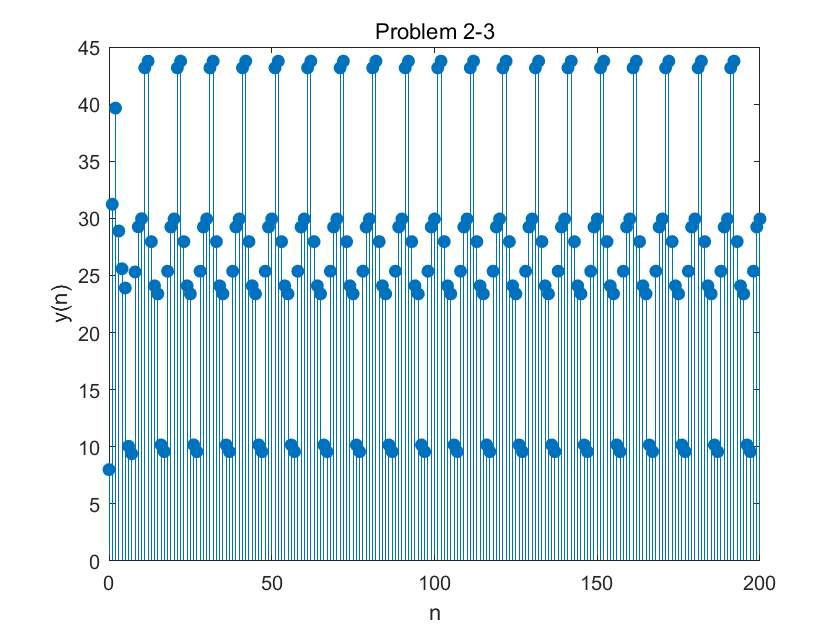

b = [1,2,0,1];                            % bm 정의
a = [1,-0.5,0.25];                        % ak 정의
n = 0:1:200;                              % n 범위 정의
x = [5+3*cos(0.2*pi*n)+4*sin(0.6*pi*n)];  % x 값 정의
y = filter(b,a,x);                        % 차분방정식으로 표현된 식의 y(n) 구하기

stem(n,y,'filled');
title('Problem 2-3');
xlabel('n'); ylabel('y(n)');

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

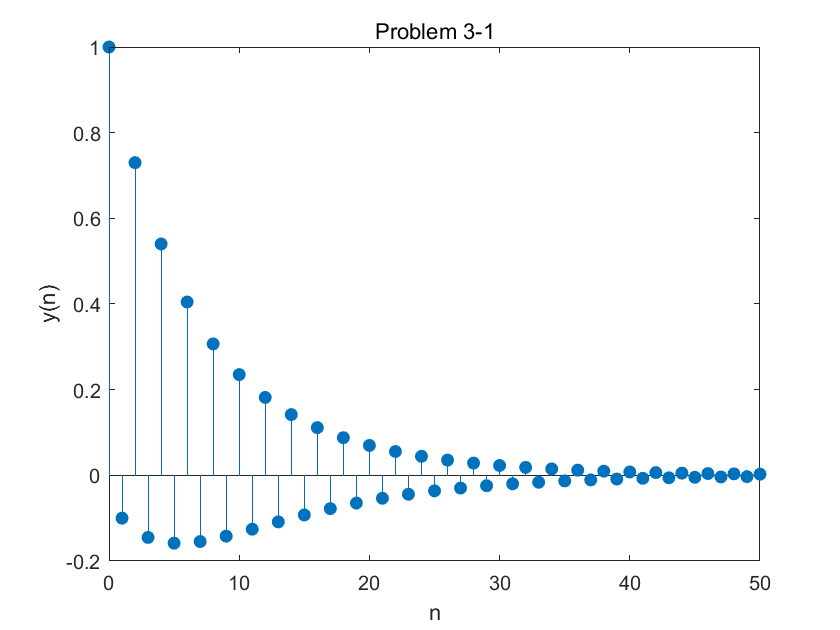

% 컨벌루전 값을 계산하면 y(n) = ((0.8).^(n+1) - (-0.9).^(n+1))/(0.8+0.9) 이다.

n = 0:1:50;                                         % n 범위 정의
y = ((0.8).^(n+1) - (-0.9).^(n+1))/(0.8+0.9);       % y 값 정의

stem(n,y,'filled');
title('Problem 3-1');
xlabel('n'); ylabel('y(n)');

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

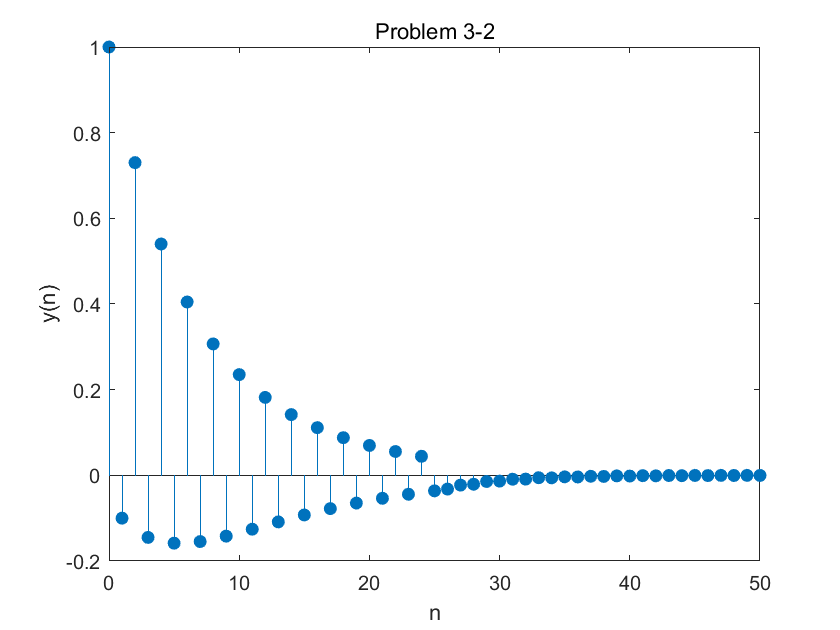

x = 0.8.^n;                                         % x 값 정의
h = (-0.9).^n;                                      % h 값 정의
x2 = x(1:26); h2 = h(1:26);                         % x(n) 을 26개 샘플로 자름
y2 = conv(h2,x2);                                   % h(n) 을 26개 샘플로 자름

stem(n,y2,'filled');
title('Problem 3-2');
xlabel('n'); ylabel('y(n)');

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

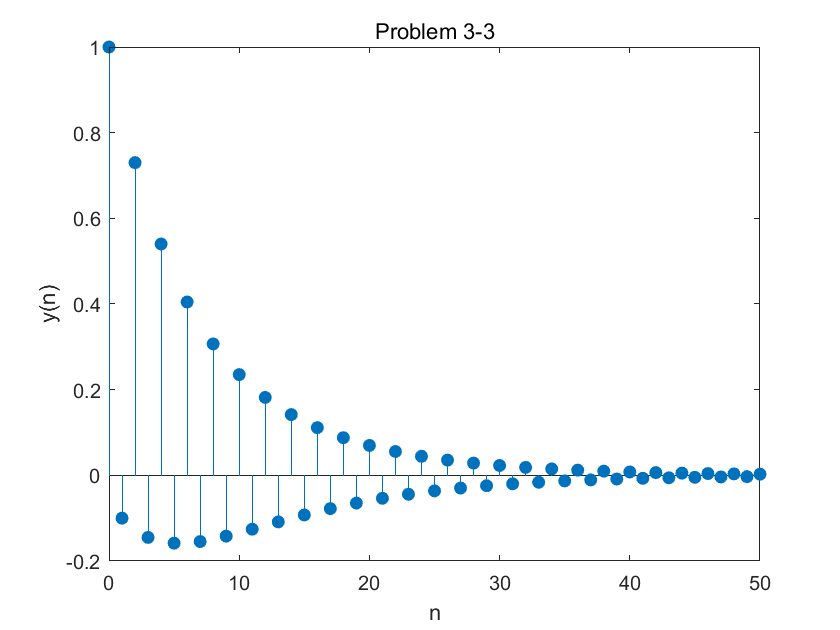

% h(n)을 이용해 차분방정식의 형태로 표현하면 y(n)+0.9*y(n-1) = x(n) 이다.

n = 0:1:50;                                         % n 범위 정의
x = 0.8.^n;                                         % x 값 정의
y3 = filter([1],[1,0.9],x);                         % 차분방정식으로 표현된 식의 y(n) 구하기

stem(n,y3,'filled');
title('Problem 3-3');
xlabel('n'); ylabel('y(n)');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

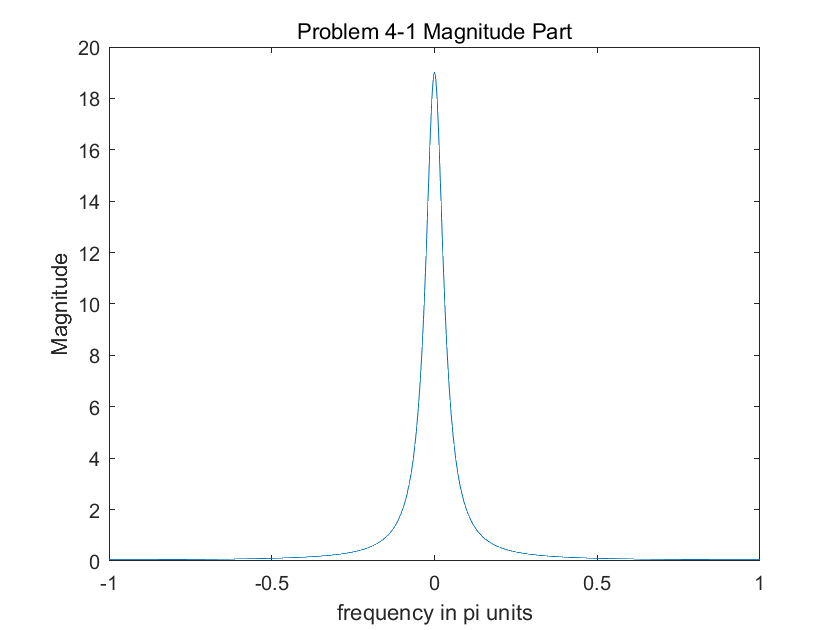

% H(exp(jw)) 를 구하면 1/(1-0.9*exp(jw)) + 1/(1-0.9*exp(-jw)) -1 이다.

w = [-500:500]*pi/500;                              % 구간 [-pi,pi]를 1001개의 점으로 나눔
H = ones(size(w))./(1-0.9*exp(j*w))+ones(size(w))./(1-0.9*exp(-j*w))-ones(size(w));
                                                    % H 값 정의
magH = abs(H);                                      % magH 정의 (크기)                                
angH = angle(H);                                    % angH 정의 (위상)

plot(w/pi,magH);
title('Problem 4-1 Magnitude Part');
xlabel('frequency in pi units'); ylabel('Magnitude');

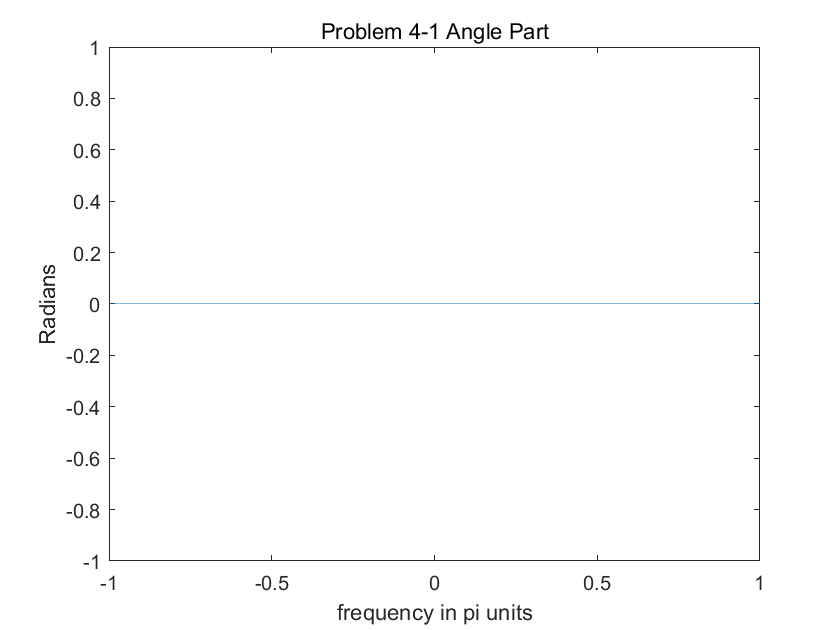

plot(w/pi,angH);
title('Problem 4-1 Angle Part');
xlabel('frequency in pi units'); ylabel('Radians');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

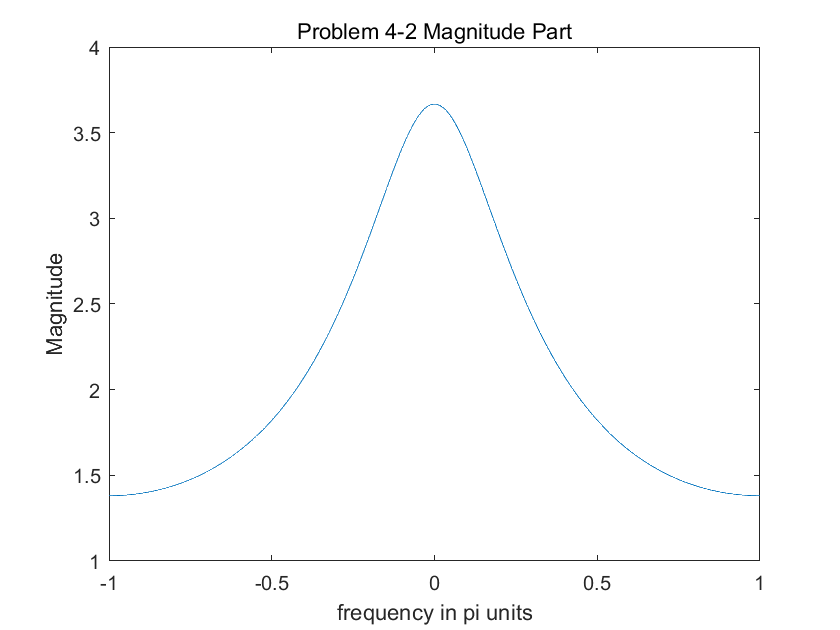

% H(exp(jw)) 를 구하면 1/(1-0.5*exp(-jw)) + 1/(1-0.4*exp(-jw)) 이다.

w = [-500:500]*pi/500;                              % 구간 [-pi,pi]를 1001개의 점으로 나눔
H = ones(size(w))./(1-0.5*exp(-j*w))+ones(size(w))./(1-0.4*exp(-j*w));
                                                    % H 값 정의
magH = abs(H);                                      % magH 정의 (크기)   
angH = angle(H);                                    % angH 정의 (위상)

plot(w/pi,magH);
title('Problem 4-2 Magnitude Part');
xlabel('frequency in pi units'); ylabel('Magnitude');

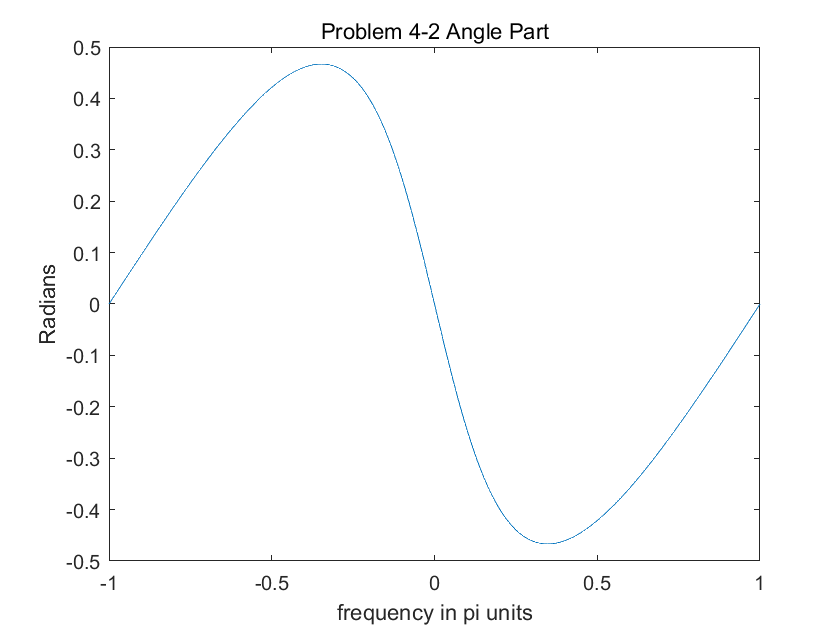

plot(w/pi,angH);
title('Problem 4-2 Angle Part');
xlabel('frequency in pi units'); ylabel('Radians');

**5번이 함수를 정의하는 문제라 5번을 마지막으로 보내어 풀었습니다!**

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

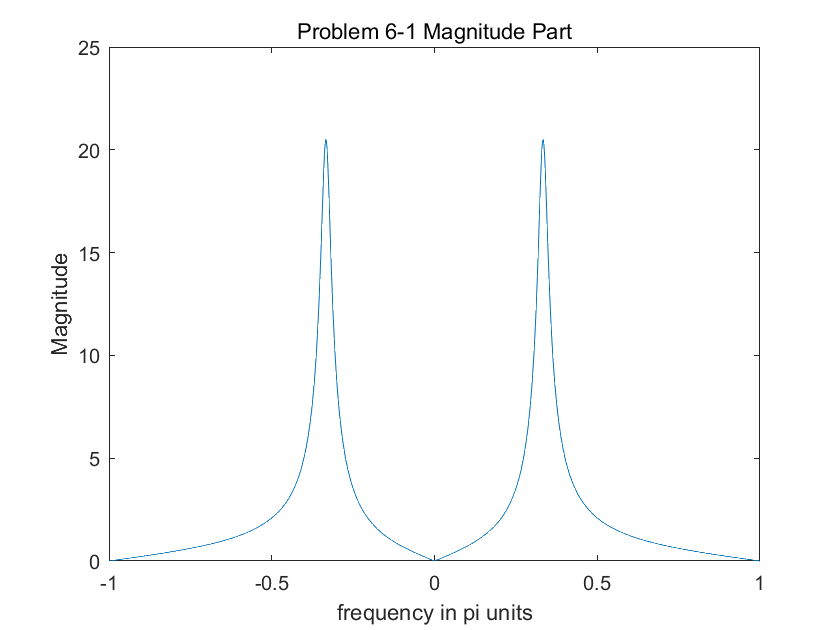

b = [1,0,-1];                                       % bm 정의
a = [1,-0.95,0.9025];                               % ak 정의
w = [-500:500]*pi/500;                              % 구간 [-pi,pi]를 1001개의 점으로 나눔
m = 0:length(b)-1; num = b*exp(-j*m'*w);            % m : b의길이      num : H의 분자값     
l = 0:length(a)-1; den = a*exp(-j*l'*w);            % l : b의길이      den : H의 분모값
H = num./den;                                       % H 정의
magH = abs(H);                                      % magH 정의 (크기) 
angH = angle(H);                                    % angH 정의 (위상)

plot(w/pi,magH);
title('Problem 6-1 Magnitude Part');
xlabel('frequency in pi units'); ylabel('Magnitude');

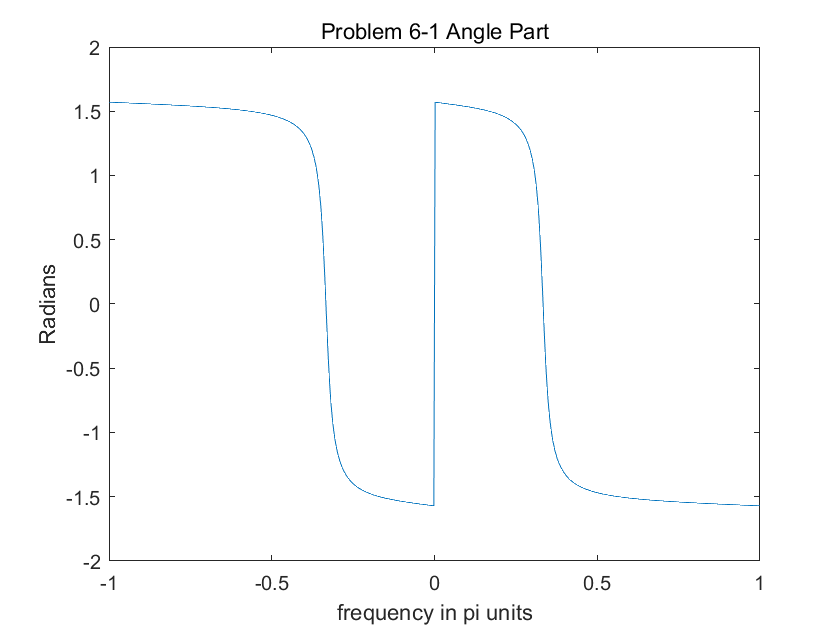

plot(w/pi,angH);
title('Problem 6-1 Angle Part');
xlabel('frequency in pi units'); ylabel('Radians');

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

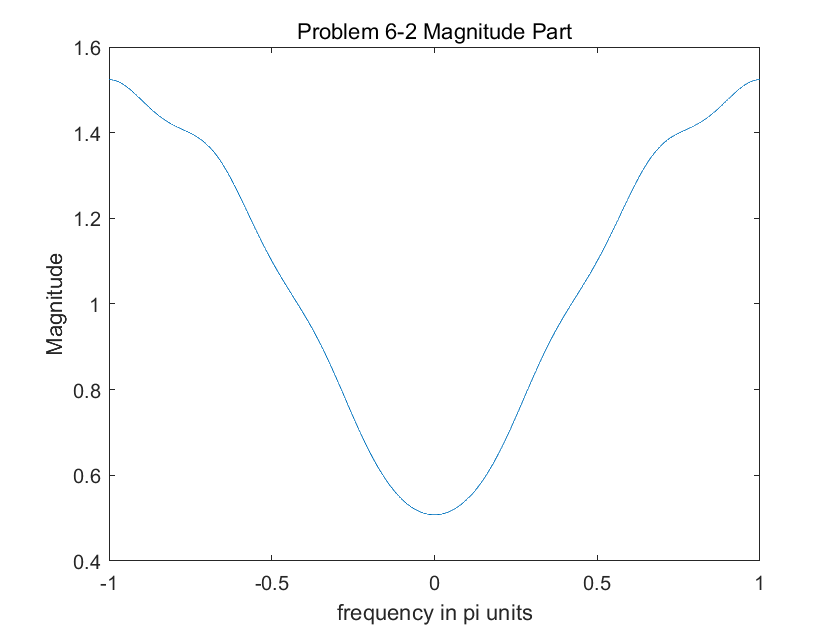

x = [0:5];                                          % ak 정의시 사용될 변수
b = [1];                                            % bm 정의
a = [0.5.^x];                                       % ak 정의
w = [-500:500]*pi/500;                              % 구간 [-pi,pi]를 1001개의 점으로 나눔
m = 0:length(b)-1; num = b*exp(-j*m'*w);            % m : b의길이      num : H의 분자값
l = 0:length(a)-1; den = a*exp(-j*l'*w);            % l : b의길이      den : H의 분모값
H = num./den;                                       % H 정의
magH = abs(H);                                      % magH 정의 (크기) 
angH = angle(H);                                    % angH 정의 (위상)

plot(w/pi,magH);                                    
title('Problem 6-2 Magnitude Part');
xlabel('frequency in pi units'); ylabel('Magnitude');

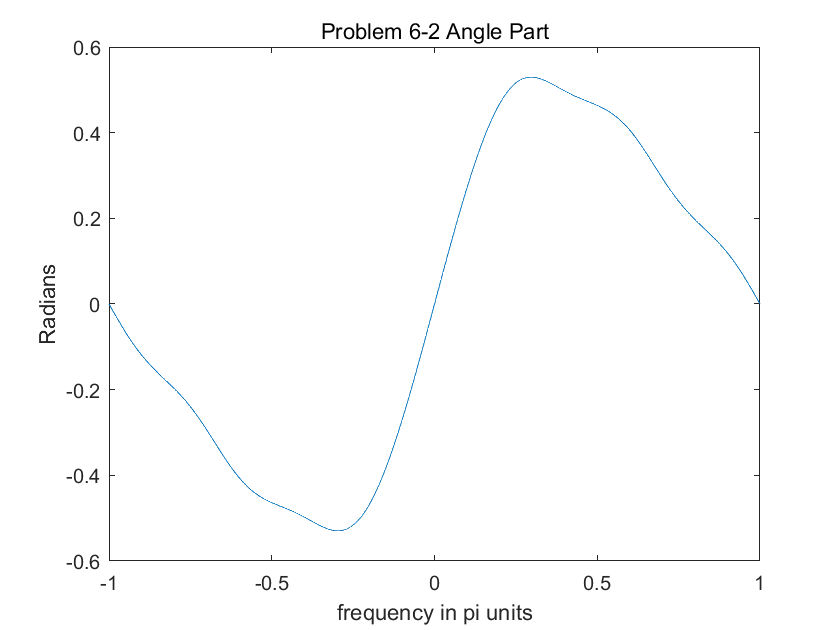

plot(w/pi,angH);
title('Problem 6-2 Angle Part');
xlabel('frequency in pi units'); ylabel('Radians');

5. (P3.17) 

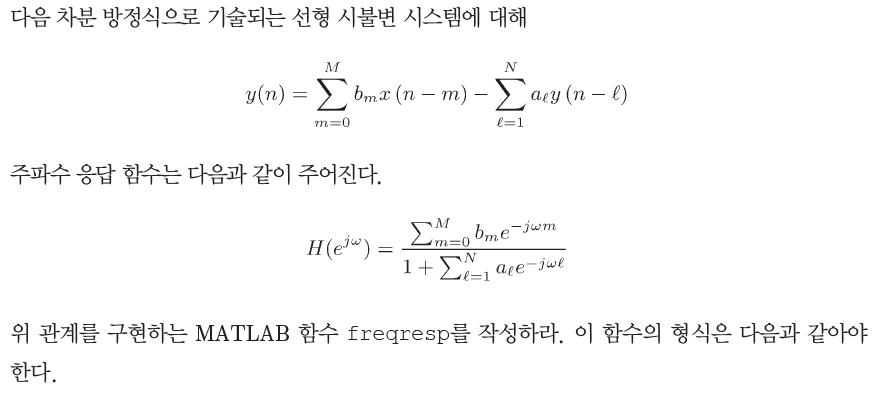

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array

b = reshape(b,1,length(b));                             % 분자 계수 배열 정의
a = reshape(a,1,length(a));                             % 분모 계수 배열 정의
w = reshape(w,1,length(w));                             % 주파수 위치 배열 정의
m = 0:length(b)-1; num = b*exp(-j*m'*w);                % m : b의길이      num : H의 분자값
l = 0:length(a)-1; den = a*exp(-j*l'*w);                % l : b의길이      den : H의 분모값
H = num./den;                                           % H 정의
end